clear; clc;

%% SECTION 1. DATA LOADING AND SPLITTING

% 1A) LOAD INDUSTRY DATA ('PortData.csv')
indData = readtable('PortData.csv');  
% Convert 'Date' (assume 'yyyy-MM-dd' format)
indData.Date = datetime(indData.Date, 'InputFormat','yyyy-MM-dd');

% 1B) LOAD FAMA-FRENCH 5 DATA ('FFama5.csv')
% in PERCENT, which we'll convert to decimals.
ffData = readtable('FFama5.csv');

if isnumeric(ffData.Date)
    ffData.Date = datetime(num2str(ffData.Date), 'InputFormat','yyyyMM');
else
    ffData.Date = datetime(ffData.Date, 'InputFormat','yyyyMM');
end

% Convert risk-free rate from percent to decimal
ffData.RF = ffData.RF / 100;
% Convert the 5 factors from percent to decimal
ffData.Mkt_RF = ffData.Mkt_RF / 100;
ffData.SMB    = ffData.SMB    / 100;
ffData.HML    = ffData.HML    / 100;
ffData.RMW    = ffData.RMW    / 100;
ffData.CMA    = ffData.CMA    / 100;

% 1C) PROCESS INDUSTRY DATA
% Convert industry returns from % to decimals
indVars = indData.Properties.VariableNames;
indVars(strcmp(indVars,'Date')) = [];
for i = 1:length(indVars)
    indData.(indVars{i}) = indData.(indVars{i}) / 100;
end

% Merge industry data with the Fama-French data to align by Date
dataInd = outerjoin(indData, ffData, 'Keys','Date','MergeKeys',true);

% Create columns of EXCESS returns for each industry: (industry return - RF)
for i = 1:length(indVars)
    dataInd.([indVars{i} '_excess']) = dataInd.(indVars{i}) - dataInd.RF;
end

% Extract industry EXCESS returns matrix
excessReturnVars_ind = strcat(indVars, '_excess');
R_ind = dataInd{:, excessReturnVars_ind};  % T x 17
datesInd = dataInd.Date;

% 1D) PROCESS FF5 DATA
% The 5 factors (Mkt_RF, SMB, HML, RMW, CMA) are already in excess-return form 
% except for the fact that Mkt_RF is (Mkt - RF). We'll treat them as "assets."
ffData5 = ffData(:,{'Date','Mkt_RF','SMB','HML','RMW','CMA','RF'});
datesFF5 = ffData5.Date;
ffVars = {'Mkt_RF','SMB','HML','RMW','CMA'};  % 5 factors
R_ff5 = ffData5{:, ffVars};  % T x 5

% 1E) SPLIT INTO IN-SAMPLE & OUT-OF-SAMPLE
startIn  = datetime(1980,1,1);
endIn    = datetime(2002,12,31);
startOut = datetime(2003,1,1);
endOut   = datetime(2024,12,31);

% Industry
inIndIdx  = (datesInd >= startIn) & (datesInd <= endIn);
outIndIdx = (datesInd >= startOut) & (datesInd <= endOut);

R_ind_in  = R_ind(inIndIdx, :);
R_ind_out = R_ind(outIndIdx, :);

% Fama-French 5
inFF5Idx  = (datesFF5 >= startIn) & (datesFF5 <= endIn);
outFF5Idx = (datesFF5 >= startOut) & (datesFF5 <= endOut);

R_ff5_in  = R_ff5(inFF5Idx, :);
R_ff5_out = R_ff5(outFF5Idx, :);

% Average risk-free rates (for reference if needed)
rf_in_ind  = mean(dataInd.RF(inIndIdx));
rf_out_ind = mean(dataInd.RF(outIndIdx));
rf_in_ff5  = mean(ffData5.RF(inFF5Idx));
rf_out_ff5 = mean(ffData5.RF(outFF5Idx));

%% SECTION 2. COMPUTE IN-SAMPLE FRONTIERS

% ========== INDUSTRY FRONTIER (IN-SAMPLE) ==========
mu_ind_in    = mean(R_ind_in)';       % 17 x 1
Sigma_ind_in = cov(R_ind_in);         % 17 x 17
nInd = length(mu_ind_in);
onesInd = ones(nInd,1);

% Global Min Var (GMV)
w_ind_gmv = (Sigma_ind_in \ onesInd) / (onesInd' * (Sigma_ind_in \ onesInd));
ret_ind_gmv = mu_ind_in' * w_ind_gmv;
vol_ind_gmv = sqrt(w_ind_gmv' * Sigma_ind_in * w_ind_gmv);
sharpe_ind_gmv = ret_ind_gmv / vol_ind_gmv;  % using excess returns => rf=0

% Tangency (Max Sharpe)
w_ind_tan = (Sigma_ind_in \ mu_ind_in) / (onesInd' * (Sigma_ind_in \ mu_ind_in));
ret_ind_tan = mu_ind_in' * w_ind_tan;
vol_ind_tan = sqrt(w_ind_tan' * Sigma_ind_in * w_ind_tan);
sharpe_ind_tan = ret_ind_tan / vol_ind_tan;

% Build entire in-sample frontier (optional) for plotting
numPoints = 100;
R_target_ind = linspace(ret_ind_gmv, max(mu_ind_in)*1.5, numPoints);
frontierVol_ind_in = zeros(numPoints,1);
options = optimoptions('quadprog','Display','off');
for i = 1:numPoints
    Aeq = [onesInd'; mu_ind_in'];
    beq = [1; R_target_ind(i)];
    [wtmp,~,flag] = quadprog(2*Sigma_ind_in,[],[],[],Aeq,beq,[],[],[],options);
    if flag>0
        frontierVol_ind_in(i) = sqrt(wtmp' * Sigma_ind_in * wtmp);
    else
        frontierVol_ind_in(i) = NaN;
    end
end

% ========== FAMA-FRENCH 5-FACTOR FRONTIER (IN-SAMPLE) ==========
mu_ff5_in    = mean(R_ff5_in)';       % 5 x 1
Sigma_ff5_in = cov(R_ff5_in);         % 5 x 5
nFF5 = length(mu_ff5_in);
onesFF5 = ones(nFF5,1);

% Global Min Var (GMV)
w_ff5_gmv = (Sigma_ff5_in \ onesFF5) / (onesFF5' * (Sigma_ff5_in \ onesFF5));
ret_ff5_gmv = mu_ff5_in' * w_ff5_gmv;
vol_ff5_gmv = sqrt(w_ff5_gmv' * Sigma_ff5_in * w_ff5_gmv);
sharpe_ff5_gmv = ret_ff5_gmv / vol_ff5_gmv;

% Tangency (Max Sharpe)
w_ff5_tan = (Sigma_ff5_in \ mu_ff5_in) / (onesFF5' * (Sigma_ff5_in \ mu_ff5_in));
ret_ff5_tan = mu_ff5_in' * w_ff5_tan;
vol_ff5_tan = sqrt(w_ff5_tan' * Sigma_ff5_in * w_ff5_tan);
sharpe_ff5_tan = ret_ff5_tan / vol_ff5_tan;

% Entire in-sample frontier (FF5) for plotting
R_target_ff5 = linspace(min(mu_ff5_in), max(mu_ff5_in)*1.5, numPoints);
frontierVol_ff5_in = zeros(numPoints,1);
for i = 1:numPoints
    Aeq = [onesFF5'; mu_ff5_in'];
    beq = [1; R_target_ff5(i)];
    [wtmp,~,flag] = quadprog(2*Sigma_ff5_in,[],[],[],Aeq,beq,[],[],[],options);
    if flag>0
        frontierVol_ff5_in(i) = sqrt(wtmp' * Sigma_ff5_in * wtmp);
    else
        frontierVol_ff5_in(i) = NaN;
    end
end

%% Robustness Testing (Bootstrap Resampling)
numBootstrap = 1000;  % Number of bootstrap iterations
bootstrapReturnsGMV = zeros(numBootstrap,1);
bootstrapReturnsTan = zeros(numBootstrap,1);

for i = 1:numBootstrap
    % Bootstrap resampling
    bootstrapSample_ind_in = R_ind_in(randi(size(R_ind_in,1), size(R_ind_in,1), 1), :);
    mu_bootstrap_in = mean(bootstrapSample_ind_in)';
    Sigma_bootstrap_in = cov(bootstrapSample_ind_in);
    
    % GMV and Tangency portfolio performance on bootstrapped sample
    w_bootstrap_gmv = (Sigma_bootstrap_in \ onesInd) / (onesInd' * (Sigma_bootstrap_in \ onesInd));
    w_bootstrap_tan = (Sigma_bootstrap_in \ mu_bootstrap_in) / (onesInd' * (Sigma_bootstrap_in \ mu_bootstrap_in));
    
    % Record returns
    bootstrapReturnsGMV(i) = mu_bootstrap_in' * w_bootstrap_gmv;
    bootstrapReturnsTan(i) = mu_bootstrap_in' * w_bootstrap_tan;
end

% Confidence intervals for GMV and Tangency returns
ciGMV = prctile(bootstrapReturnsGMV, [2.5 97.5]);
ciTan = prctile(bootstrapReturnsTan, [2.5 97.5]);

fprintf('\n=== Robustness Testing Results (Bootstrap Resampling) ===\n');


=== Robustness Testing Results (Bootstrap Resampling) ===


fprintf('GMV Return Confidence Interval: [%.4f, %.4f]\n', ciGMV(1), ciGMV(2));

GMV Return Confidence Interval: [0.0010, 0.0096]


fprintf('Tangency Return Confidence Interval: [%.4f, %.4f]\n', ciTan(1), ciTan(2));

Tangency Return Confidence Interval: [0.0145, 0.1018]




%% SECTION 3. DEFINE IN-SAMPLE & OUT-OF-SAMPLE PORTFOLIO RETURNS

% Industry in-sample returns
portRet_ind_in_gmv = R_ind_in * w_ind_gmv; 
portRet_ind_in_tan = R_ind_in * w_ind_tan;

% Industry out-of-sample returns
portRet_ind_out_gmv = R_ind_out * w_ind_gmv;
portRet_ind_out_tan = R_ind_out * w_ind_tan;

% FF5 in-sample returns
portRet_ff5_in_gmv = R_ff5_in * w_ff5_gmv;
portRet_ff5_in_tan = R_ff5_in * w_ff5_tan;

% FF5 out-of-sample returns
portRet_ff5_out_gmv = R_ff5_out * w_ff5_gmv;
portRet_ff5_out_tan = R_ff5_out * w_ff5_tan;

%% SECTION 4. EVALUATE PERFORMANCE

% ---------- Industry: In-Sample ----------
inMean_ind_gmv   = mean(portRet_ind_in_gmv);
inVol_ind_gmv    = std(portRet_ind_in_gmv);
inSharpe_ind_gmv = inMean_ind_gmv / inVol_ind_gmv;

inMean_ind_tan   = mean(portRet_ind_in_tan);
inVol_ind_tan    = std(portRet_ind_in_tan);
inSharpe_ind_tan = inMean_ind_tan / inVol_ind_tan;

% ---------- Industry: Out-of-Sample ----------
outMean_ind_gmv   = mean(portRet_ind_out_gmv);
outVol_ind_gmv    = std(portRet_ind_out_gmv);
outSharpe_ind_gmv = outMean_ind_gmv / outVol_ind_gmv;

outMean_ind_tan   = mean(portRet_ind_out_tan);
outVol_ind_tan    = std(portRet_ind_out_tan);
outSharpe_ind_tan = outMean_ind_tan / outVol_ind_tan;

% ---------- FF5: In-Sample ----------
inMean_ff5_gmv   = mean(portRet_ff5_in_gmv);
inVol_ff5_gmv    = std(portRet_ff5_in_gmv);
inSharpe_ff5_gmv = inMean_ff5_gmv / inVol_ff5_gmv;

inMean_ff5_tan   = mean(portRet_ff5_in_tan);
inVol_ff5_tan    = std(portRet_ff5_in_tan);
inSharpe_ff5_tan = inMean_ff5_tan / inVol_ff5_tan;

% ---------- FF5: Out-of-Sample ----------
outMean_ff5_gmv   = mean(portRet_ff5_out_gmv);
outVol_ff5_gmv    = std(portRet_ff5_out_gmv);
outSharpe_ff5_gmv = outMean_ff5_gmv / outVol_ff5_gmv;

outMean_ff5_tan   = mean(portRet_ff5_out_tan);
outVol_ff5_tan    = std(portRet_ff5_out_tan);
outSharpe_ff5_tan = outMean_ff5_tan / outVol_ff5_tan;

%% Print out summary stats
fprintf('=== INDUSTRY In-Sample ===\n');

=== INDUSTRY In-Sample ===


fprintf('GMV: Ret=%.4f, Vol=%.4f, Sharpe=%.4f\n', ret_ind_gmv, vol_ind_gmv, sharpe_ind_gmv);

GMV: Ret=0.0055, Vol=0.0341, Sharpe=0.1615


fprintf('    Realized In-Sample: Mean=%.4f, Vol=%.4f, Sharpe=%.4f\n',...
    inMean_ind_gmv, inVol_ind_gmv, inSharpe_ind_gmv);

    Realized In-Sample: Mean=0.0055, Vol=0.0341, Sharpe=0.1615


fprintf('TAN: Ret=%.4f, Vol=%.4f, Sharpe=%.4f\n', ret_ind_tan, vol_ind_tan, sharpe_ind_tan);

TAN: Ret=0.0137, Vol=0.0538, Sharpe=0.2551


fprintf('    Realized In-Sample: Mean=%.4f, Vol=%.4f, Sharpe=%.4f\n',...
    inMean_ind_tan, inVol_ind_tan, inSharpe_ind_tan);

    Realized In-Sample: Mean=0.0137, Vol=0.0538, Sharpe=0.2551



fprintf('\n=== INDUSTRY Out-of-Sample ===\n');


=== INDUSTRY Out-of-Sample ===


fprintf('GMV: Mean=%.4f, Vol=%.4f, Sharpe=%.4f\n', outMean_ind_gmv, outVol_ind_gmv, outSharpe_ind_gmv);

GMV: Mean=0.0076, Vol=0.0367, Sharpe=0.2064


fprintf('TAN: Mean=%.4f, Vol=%.4f, Sharpe=%.4f\n', outMean_ind_tan, outVol_ind_tan, outSharpe_ind_tan);

TAN: Mean=0.0075, Vol=0.0427, Sharpe=0.1758



fprintf('\n=== FF5 In-Sample ===\n');


=== FF5 In-Sample ===


fprintf('GMV: Ret=%.4f, Vol=%.4f, Sharpe=%.4f\n', ret_ff5_gmv, vol_ff5_gmv, sharpe_ff5_gmv);

GMV: Ret=0.0039, Vol=0.0103, Sharpe=0.3831


fprintf('    Realized In-Sample: Mean=%.4f, Vol=%.4f, Sharpe=%.4f\n',...
    inMean_ff5_gmv, inVol_ff5_gmv, inSharpe_ff5_gmv);

    Realized In-Sample: Mean=0.0039, Vol=0.0103, Sharpe=0.3831


fprintf('TAN: Ret=%.4f, Vol=%.4f, Sharpe=%.4f\n', ret_ff5_tan, vol_ff5_tan, sharpe_ff5_tan);

TAN: Ret=0.0044, Vol=0.0108, Sharpe=0.4030


fprintf('    Realized In-Sample: Mean=%.4f, Vol=%.4f, Sharpe=%.4f\n',...
    inMean_ff5_tan, inVol_ff5_tan, inSharpe_ff5_tan);

    Realized In-Sample: Mean=0.0044, Vol=0.0108, Sharpe=0.4030



fprintf('\n=== FF5 Out-of-Sample ===\n');


=== FF5 Out-of-Sample ===


fprintf('GMV: Mean=%.4f, Vol=%.4f, Sharpe=%.4f\n', outMean_ff5_gmv, outVol_ff5_gmv, outSharpe_ff5_gmv);

GMV: Mean=0.0025, Vol=0.0123, Sharpe=0.2013


fprintf('TAN: Mean=%.4f, Vol=%.4f, Sharpe=%.4f\n', outMean_ff5_tan, outVol_ff5_tan, outSharpe_ff5_tan);

TAN: Mean=0.0028, Vol=0.0126, Sharpe=0.2221



%% SECTION 5. JOBSON-KORKIE & LEDOIT-WOLF TESTS
% Compare each portfolio's in-sample Sharpe vs. out-of-sample Sharpe
% for Industry and for FF5. 
n_ind_in  = size(R_ind_in,1);
n_ind_out = size(R_ind_out,1);
n_ff5_in  = size(R_ff5_in,1);
n_ff5_out = size(R_ff5_out,1);

% Helper for Jobson-Korkie:
% JK_stat = (S_in - S_out) / sqrt( var(S_in) + var(S_out) )
% with var(S) approx (1 + 0.5 * S^2) / T under i.i.d. assumption
JKtest = @(S_in, S_out, N_in, N_out) ...
    (S_in - S_out) ./ sqrt( (1 + 0.5*S_in^2)/N_in + (1 + 0.5*S_out^2)/N_out );

% ---------- Industry: GMV ----------
JK_stat_ind_gmv = JKtest(inSharpe_ind_gmv, outSharpe_ind_gmv, n_ind_in, n_ind_out);
p_val_ind_gmv   = 2 * (1 - normcdf(abs(JK_stat_ind_gmv)));

% ---------- Industry: TAN ----------
JK_stat_ind_tan = JKtest(inSharpe_ind_tan, outSharpe_ind_tan, n_ind_in, n_ind_out);
p_val_ind_tan   = 2 * (1 - normcdf(abs(JK_stat_ind_tan)));

% ---------- FF5: GMV ----------
JK_stat_ff5_gmv = JKtest(inSharpe_ff5_gmv, outSharpe_ff5_gmv, n_ff5_in, n_ff5_out);
p_val_ff5_gmv   = 2 * (1 - normcdf(abs(JK_stat_ff5_gmv)));

% ---------- FF5: TAN ----------
JK_stat_ff5_tan = JKtest(inSharpe_ff5_tan, outSharpe_ff5_tan, n_ff5_in, n_ff5_out);
p_val_ff5_tan   = 2 * (1 - normcdf(abs(JK_stat_ff5_tan)));

fprintf('\n=== Jobson-Korkie Test (Comparing In-Sample vs. OOS Sharpe) ===\n');


=== Jobson-Korkie Test (Comparing In-Sample vs. OOS Sharpe) ===


fprintf('Industry GMV: JK=%.4f, p=%.4f\n', JK_stat_ind_gmv, p_val_ind_gmv);

Industry GMV: JK=-0.5179, p=0.6045


fprintf('Industry TAN: JK=%.4f, p=%.4f\n', JK_stat_ind_tan, p_val_ind_tan);

Industry TAN: JK=0.9102, p=0.3627


fprintf('FF5 GMV:      JK=%.4f, p=%.4f\n', JK_stat_ff5_gmv, p_val_ff5_gmv);

FF5 GMV:      JK=2.0645, p=0.0390


fprintf('FF5 TAN:      JK=%.4f, p=%.4f\n', JK_stat_ff5_tan, p_val_ff5_tan);

FF5 TAN:      JK=2.0483, p=0.0405



% ---------- Ledoit-Wolf Tests (Bootstrap) ----------
B = 1000; % # of bootstrap iterations

% Industry GMV
[LW_ind_gmv, pLW_ind_gmv] = LedoitWolfTest(portRet_ind_in_gmv, portRet_ind_out_gmv, B);
% Industry TAN
[LW_ind_tan, pLW_ind_tan] = LedoitWolfTest(portRet_ind_in_tan, portRet_ind_out_tan, B);

% FF5 GMV
[LW_ff5_gmv, pLW_ff5_gmv] = LedoitWolfTest(portRet_ff5_in_gmv, portRet_ff5_out_gmv, B);
% FF5 TAN
[LW_ff5_tan, pLW_ff5_tan] = LedoitWolfTest(portRet_ff5_in_tan, portRet_ff5_out_tan, B);

fprintf('\n=== Ledoit-Wolf Test (Bootstrap) ===\n');


=== Ledoit-Wolf Test (Bootstrap) ===


fprintf('Industry GMV: Stat=%.4f, p=%.4f\n', LW_ind_gmv, pLW_ind_gmv);

Industry GMV: Stat=-0.4779, p=1.3420


fprintf('Industry TAN: Stat=%.4f, p=%.4f\n', LW_ind_tan, pLW_ind_tan);

Industry TAN: Stat=0.9135, p=1.0940


fprintf('FF5 GMV:      Stat=%.4f, p=%.4f\n', LW_ff5_gmv, pLW_ff5_gmv);

FF5 GMV:      Stat=1.9181, p=0.9760


fprintf('FF5 TAN:      Stat=%.4f, p=%.4f\n', LW_ff5_tan, pLW_ff5_tan);

FF5 TAN:      Stat=1.9653, p=1.0560


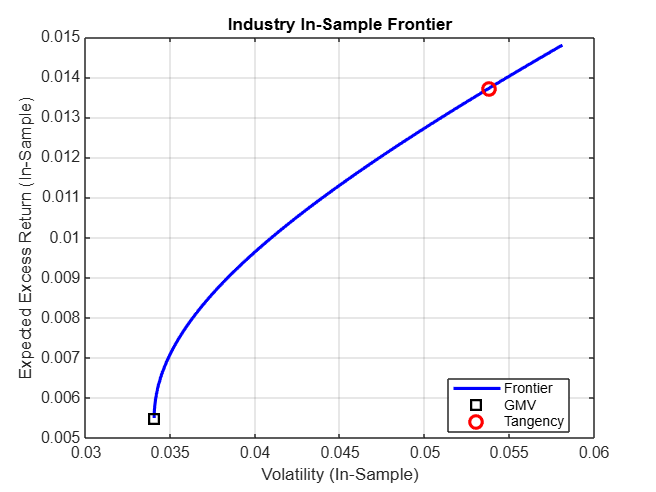


%% SECTION 6. PLOT IN-SAMPLE FRONTIERS

% ---------- Industry Frontier (In-Sample) ----------
figure('Name','In-Sample Frontier: Industry');
plot(frontierVol_ind_in, R_target_ind, 'b-', 'LineWidth',2); hold on;
plot(vol_ind_gmv, ret_ind_gmv, 'ks', 'MarkerSize',8,'LineWidth',2);
plot(vol_ind_tan, ret_ind_tan, 'ro', 'MarkerSize',8,'LineWidth',2);
xlabel('Volatility (In-Sample)');
ylabel('Expected Excess Return (In-Sample)');
title('Industry In-Sample Frontier');
legend('Frontier','GMV','Tangency','Location','best');
grid on;

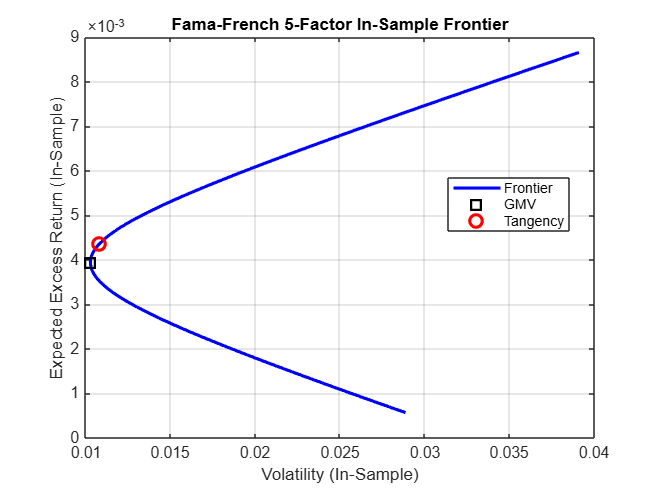


% ---------- FF5 Frontier (In-Sample) ----------
figure('Name','In-Sample Frontier: FF5');
plot(frontierVol_ff5_in, R_target_ff5, 'b-', 'LineWidth',2); hold on;
plot(vol_ff5_gmv, ret_ff5_gmv, 'ks', 'MarkerSize',8,'LineWidth',2);
plot(vol_ff5_tan, ret_ff5_tan, 'ro', 'MarkerSize',8,'LineWidth',2);
xlabel('Volatility (In-Sample)');
ylabel('Expected Excess Return (In-Sample)');
title('Fama-French 5-Factor In-Sample Frontier');
legend('Frontier','GMV','Tangency','Location','best');
grid on;

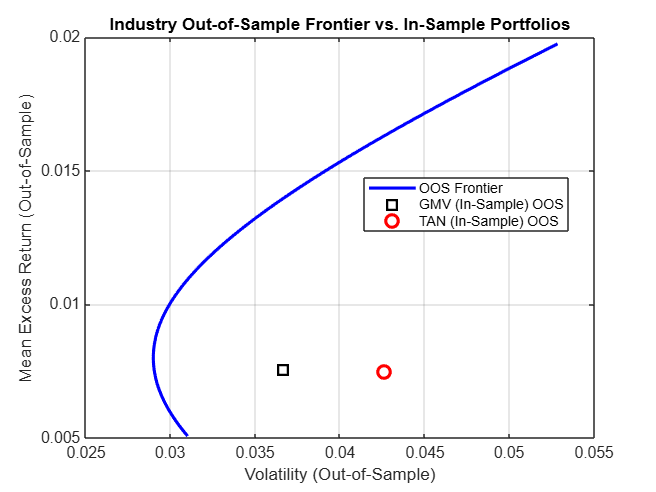


%% SECTION 7. PLOT OUT-OF-SAMPLE FRONTIERS + REALIZED POINTS

% ========== Industry: Out-of-Sample Frontier ==========
mu_ind_out    = mean(R_ind_out)';   % 17 x 1
Sigma_ind_out = cov(R_ind_out);     % 17 x 17
R_target_ind_oos = linspace(min(mu_ind_out), max(mu_ind_out)*1.5, numPoints);
frontierVol_ind_out = zeros(numPoints,1);
for i = 1:numPoints
    Aeq = [onesInd'; mu_ind_out'];
    beq = [1; R_target_ind_oos(i)];
    [wtmp,~,flag] = quadprog(2*Sigma_ind_out,[],[],[],Aeq,beq,[],[],[],options);
    if flag>0
        frontierVol_ind_out(i) = sqrt(wtmp' * Sigma_ind_out * wtmp);
    else
        frontierVol_ind_out(i) = NaN;
    end
end

figure('Name','Out-of-Sample Frontier: Industry');
plot(frontierVol_ind_out, R_target_ind_oos, 'b-', 'LineWidth',2); hold on;
plot(outVol_ind_gmv, outMean_ind_gmv, 'ks','MarkerSize',8,'LineWidth',2);
plot(outVol_ind_tan, outMean_ind_tan, 'ro','MarkerSize',8,'LineWidth',2);
xlabel('Volatility (Out-of-Sample)');
ylabel('Mean Excess Return (Out-of-Sample)');
title('Industry Out-of-Sample Frontier vs. In-Sample Portfolios');
legend('OOS Frontier','GMV (In-Sample) OOS','TAN (In-Sample) OOS','Location','best');
grid on;

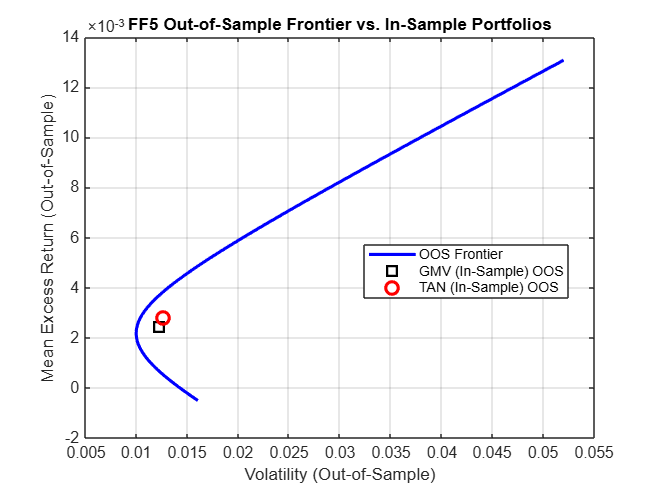


% ========== FF5: Out-of-Sample Frontier ==========
mu_ff5_out    = mean(R_ff5_out)';   % 5 x 1
Sigma_ff5_out = cov(R_ff5_out);     % 5 x 5
R_target_ff5_oos = linspace(min(mu_ff5_out), max(mu_ff5_out)*1.5, numPoints);
frontierVol_ff5_out = zeros(numPoints,1);
for i = 1:numPoints
    Aeq = [onesFF5'; mu_ff5_out'];
    beq = [1; R_target_ff5_oos(i)];
    [wtmp,~,flag] = quadprog(2*Sigma_ff5_out,[],[],[],Aeq,beq,[],[],[],options);
    if flag>0
        frontierVol_ff5_out(i) = sqrt(wtmp' * Sigma_ff5_out * wtmp);
    else
        frontierVol_ff5_out(i) = NaN;
    end
end

figure('Name','Out-of-Sample Frontier: FF5');
plot(frontierVol_ff5_out, R_target_ff5_oos, 'b-', 'LineWidth',2); hold on;
plot(outVol_ff5_gmv, outMean_ff5_gmv, 'ks','MarkerSize',8,'LineWidth',2);
plot(outVol_ff5_tan, outMean_ff5_tan, 'ro','MarkerSize',8,'LineWidth',2);
xlabel('Volatility (Out-of-Sample)');
ylabel('Mean Excess Return (Out-of-Sample)');
title('FF5 Out-of-Sample Frontier vs. In-Sample Portfolios');
legend('OOS Frontier','GMV (In-Sample) OOS','TAN (In-Sample) OOS','Location','best');
grid on;



%% Ledoit-Wolf Test Function (Bootstrap)

function [LW_stat, p_value] = LedoitWolfTest(r_in, r_out, B)
% LedoitWolfTest uses a simple bootstrap approach to test the null hypothesis
% that the in-sample Sharpe ratio = out-of-sample Sharpe ratio.
%
% INPUT:
%   r_in  - Vector of in-sample returns
%   r_out - Vector of out-of-sample returns
%   B     - Number of bootstrap replications
%
% OUTPUT:
%   LW_stat  - Test statistic: observed difference / bootstrap std
%   p_value  - Two-sided p-value

    if nargin < 3, B = 1000; end
    S_in = mean(r_in) / std(r_in);
    S_out = mean(r_out) / std(r_out);
    diff_obs = S_in - S_out;

    n_in = length(r_in);
    n_out = length(r_out);

    bootDiffs = zeros(B,1);
    for b = 1:B
        % Resample with replacement from in-sample & out-of-sample returns
        boot_in  = r_in(randi(n_in, n_in,1));
        boot_out = r_out(randi(n_out, n_out,1));
        S_in_b   = mean(boot_in) / std(boot_in);
        S_out_b  = mean(boot_out) / std(boot_out);
        bootDiffs(b) = S_in_b - S_out_b;
    end

    se_boot = std(bootDiffs);
    LW_stat = diff_obs / se_boot;
    p_value = 2 * mean(abs(bootDiffs) >= abs(diff_obs));
end
